# Elaborato FFT - Analisi di segnali sonori

Nel file notetest.wav vi è un segnale sonoro costituito da 5 note: a,b,c,d,e, ognuna della durata di 0.25sec., con frequenza di campionamento Fs=16000. Leggere il file in Matlab, ascoltarlo, fare il grafico del periodogramma in Hz e in decibel, combinare le note per ottenere il brano musicale: a a b c c b a d e e d a a d d.. Farne lo spettrogramma usando la finestra di Blackman con N=512 e un overlap del 2%. Scrivere il brano in un file.wav ed ascoltarlo. 

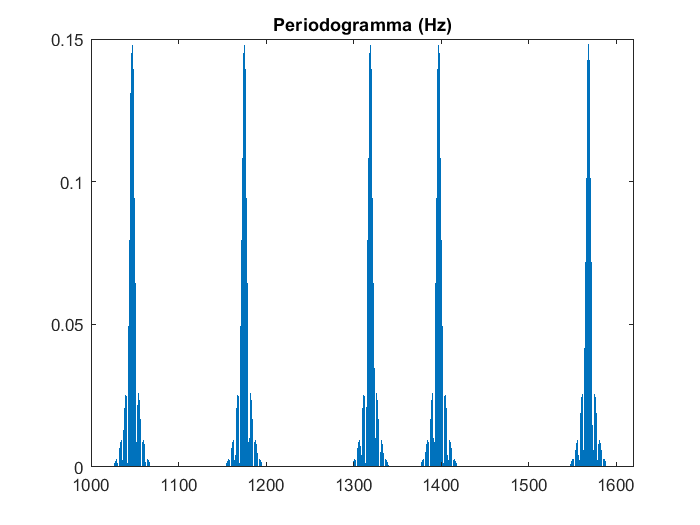

clear all
clc
[y, Fc] = audioread('notetest.wav');
n = length(y);

Y = fft(y);
f = (0:floor(n/2))*Fc/n;
amp = 2*abs(Y(1:floor(n/2)+1)/n);

figure()
stem(f,amp,'Marker','none'), xlim([1000 1620]), title('Periodogramma (Hz)')

Si osservi che nel grafico si è preferito limitare l'asse delle frequenze, evidenziando solo quelle di interesse.

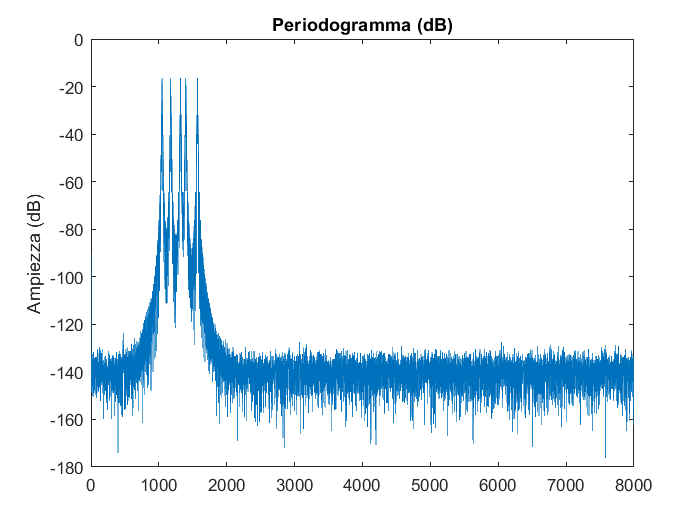

ampdb = mag2db(amp);
plot(f,ampdb), title('Periodogramma (dB)'), ylabel('Ampiezza (dB)');

Potrei separare le note ragionando sulla frequenza come mostrato di seguito:

% A = Y;
% idx = find(f>=1100);
% A(idx) = 0; A(n+2-idx) = 0;
% A = ifft(A);
% soundsc(real(A))

Ma poiché tutte le note presenti nel file audio hanno la stessa temporale, è molto più immediato ragionare nel dominio del tempo:

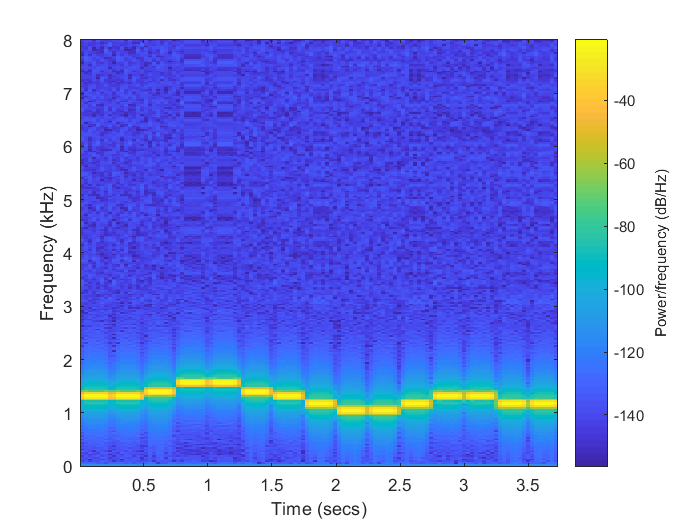

passo = floor(n/5);
A = y(1:passo); 
B = y(passo+1 : 2*passo); 
C = y(2*passo+1 : 3*passo); 
D = y(3*passo+1 : 4*passo);
E = y(4*passo+1 : 5*passo);

notes = [A; A; B; C; C; B; A; D; E; E; D; A; A; D; D];

audiowrite('innoallagioia.wav',notes,Fc);
[y, Fc] = audioread('innoallagioia.wav');
sound(y,Fc);

spectrogram(y,blackman(512),floor(0.02*512),512,Fc,'yaxis')